Starting registration...
 
 Iteration   Func-count         f(x)         Procedure
     0            1      2.84869e+08         
Iteration going on
     1            3      2.84856e+08         initial simplex
Iteration going on
     2            5      2.84806e+08         expand
Iteration going on
     3            7      2.84754e+08         expand
Iteration going on
     4            9       2.8463e+08         expand
Iteration going on
     5           11      2.84464e+08         expand
Iteration going on
     6           13      2.84134e+08         expand
Iteration going on
     7           15      2.83641e+08         expand
Iteration going on
     8           17      2.82744e+08         expand
Iteration going on
     9           19      2.81339e+08         expand
Iteration going on
    10           21      2.78927e+08         expand
Iteration going on
    11           23      2.75142e+08         expand
Iteration going on
    12           25      2.69078e+08         expand
Iteration g

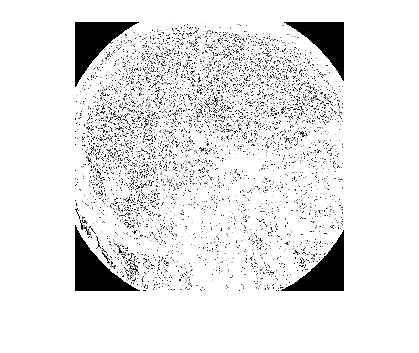

Error using movie
Repetition count and frame order list must be numeric, with finite values

Error in movie

Error in movie

Error in movie

Error in regOutFun (line 59)
            movie(frames, F,1, 2);  % play once at 2 frames/sec

Error in hw4_Q5>@(x,optimVals,state)regOutFun(x,optimVals,state,live,mask,param) (<a href="

% 1. Initial Setup
clc; clear;
live = imread('live_new.tif');    % Reference image (with contrast)
mask = imread('mask_new.tif');    % Floating image (no contrast)
[m, n] = size(live);

% Convert to double for numerical operations
live = double(live);
mask = double(mask);

% Calculate initial subtraction (before registration)
diff_before = live - mask;

% Setup optimization parameters
param = struct();
param.scaling = 1;  % Start with no scaling

% Setup cost function
costF = @(t) SSE(live, mask, t(1), t(2), param);

% Create the output function with additional parameters
outfun = @(x, optimVals, state) regOutFun(x, optimVals, state, live, mask, param);

% Set optimization options
options = optimset(...
    'Display', 'iter',...
    'TolFun', 1e-3,...
    'TolX', 1e-3,...
    'MaxIter', 200,...
    'OutputFcn', outfun);

% Run optimization
[t_optimal, fval, exitflag, output] = fminsearch(costF, [0,0], options);


% Apply optimal translation to create registered image
translated = imtranslate(mask, [t_optimal(1), t_optimal(2)], 'OutputView', 'same');

% Calculate final subtraction
diff_after = live - translated;

% Display results
figure('Position', [100 100 1200 800]);
tiledlayout(2,2)

% Original live image
nexttile
imagesc(live)
colormap('gray')
title('Live Image (with contrast)')
colorbar

% Original mask image
nexttile
imagesc(mask)
title('Mask Image (no contrast)')
colormap('gray')
colorbar

% Subtraction before registration
nexttile
imagesc(diff_before)
title('Subtraction Before Registration')
colormap('gray')
colorbar

% Subtraction after registration
nexttile
imagesc(diff_after)
title('Subtraction After Registration')
colormap('gray')
colorbar

% Print optimization results
fprintf('\nOptimization Results:\n');
fprintf('Optimal translation parameters:\n');
fprintf('X translation: %.4f pixels\n', t_optimal(1));
fprintf('Y translation: %.4f pixels\n', t_optimal(2));
fprintf('Final cost value: %.4f\n', fval);
fprintf('Number of iterations: %d\n', output.iterations);
fprintf('Exit flag: %d\n', exitflag);

% Save results
save('dsa_registration_results.mat', 't_optimal', 'fval', 'output');